# Q1

u = [3, 1, -2]

u =      3     1    -2


null(u)

ans =    -0.2673    0.5345
    0.9604    0.0793
    0.0793    0.8414


## Q2

V1 = [2,0,1]; V2 = [1,1,1];
A = [V1; V2];
N = null(A)

N =    -0.4082
   -0.4082
    0.8165


## Q3

A = [1 1 3; 2 -3 1]

A =      1     1     3
     2    -3     1


B = [0; 0]

B =      0
     0


V =  (A\B)

V =      0
     0
     0


null(V)

ans = 1

## Q4

v1 = [1 0 1]

v1 =      1     0     1


v2 = [-2 0 0]

v2 =     -2     0     0


v3 = [0 0 3]

v3 =      0     0     3


A = [v1; v2; v3]

A =      1     0     1
    -2     0     0
     0     0     3


v4 = null(A)'

v4 =     0.0000   -1.0000   -0.0000


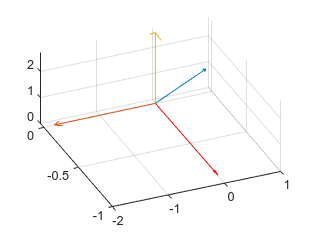

% extras
quiver3(0,0,0,v1(1,1),v1(1,2),v1(1,3))
hold on
quiver3(0,0,0,v2(1,1),v2(1,2),v2(1,3))
quiver3(0,0,0,v3(1,1),v3(1,2),v3(1,3))
quiver3(0,0,0,v4(1,1),v4(1,2),v4(1,3),"Color","red")

hold off

## Q5

v1 = [3, -5, 2]

v1 =      3    -5     2


v2 = [2, 1, 4]

v2 =      2     1     4


A =[v1;v2]

A =      3    -5     2
     2     1     4


null(A)

ans =    -0.8216
   -0.2988
    0.4855


## Q6

v1 = [4, 1, -2, 0]
v2 = [-1, 2, -1, 1]
A = [v1; v2]
null(A)

## Q7

V1 = [0  1 2]

V1 =      0     1     2


V2 = [1 -1 0]

V2 =      1    -1     0


V3 = [3  1 8]

V3 =      3     1     8


A = [V1; V2; V3];
N = null(A)

N =    -0.6667
   -0.6667
    0.3333


[RR,ic]=rref(A)

RR =      1     0     2
     0     1     2
     0     0     0


ic =      1     2


r=length(ic)

r = 2

R=RR(1:r,:)

R =      1     0     2
     0     1     2


for i=1:size(R,1);
    for j=1:size(N,2);
        if round(dot(R(i,:),N(:,j)))==0
            disp('They are orthogonal complements of each other')
        else
            disp('They are not orthogonal complements of each other')
        end
    end
end

They are orthogonal complements of each other
They are orthogonal complements of each other
